%change1:trainingWindowIntdisStForR1
%change2:hs
%change3:Human
%change4:anycell="K562";   
%change5: str =["
%change6:str_png =["hsK562","hsGM12878","hs501mel","hs12Z"] 


%titleString = sprintf("Human Lung test %s ROC Curve", string(str(i)));
%title(titleString);
anycell="K562";   %only change the cell name
openfile = sprintf("trainingWindowIntdisStForR_hs%s.bed", anycell);
%fileID = fopen("trainingWindowIntdisStForR1_hsLung.bed");   %%%%%%%%%%%%%
fileID = fopen(openfile)

fileID = 570

TrainwindowdatadisKc167 = textscan(fileID, '%s %f %f %f %f %f %f %f');
trainingdischiapetKc167 = [TrainwindowdatadisKc167{2:8}];

predictorNames = {'EGC', 'GS', 'DIS', 'EWS', 'GWS', 'EEC'};
inputTable = array2table(trainingdischiapetKc167, 'VariableNames', {'EGC', 'GS', 'DIS', 'EWS', 'GWS', 'EEC', 'column_7'});
predictors = inputTable(:, predictorNames);
response = inputTable.column_7;

% Ensemble bagged
%%%%%% template = templateTree('MaxNumSplits', 30);
%%%%%% classificationEnsemble = fitcensemble(predictors, response, 'Method', 'AdaBoostM1', 'NumLearningCycles', 30, 'Learners', template, 'LearnRate', 0.8, 'ClassNames', [1; 2]);
%%%%%% partitionedModel = crossval(classificationEnsemble, 'KFold', 10);
%%%%%% [validationPredictions, validationScores] = kfoldPredict(partitionedModel);

%#####################

template = templateTree('MaxNumSplits', 24);
classificationEnsemble = fitcensemble(predictors, response, 'Method', 'GentleBoost', 'NumLearningCycles', 5, 'Learners', template, 'LearnRate', 0.8, 'ClassNames', [1; 2]);
partitionedModel = crossval(classificationEnsemble, 'KFold', 10);
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);


%######################

[Xsvm, Ysvm, Tsvm, AUCsvm] = perfcurve(trainingdischiapetKc167(:, 7), validationScores(:, 1), 1);
AUCsvm

AUCsvm = 0.9585

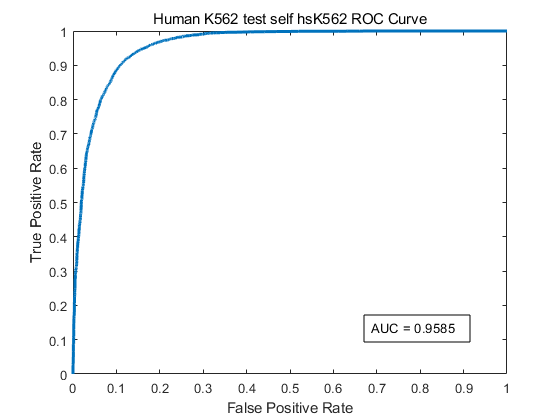

    plot(Xsvm, Ysvm,'LineWidth', 1.9);
    xlabel('False Positive Rate');
    ylabel('True Positive Rate');
    %title('Human Lung test hsLung ROC Curve');
    titleString = sprintf("Human %s test self hs%s ROC Curve", anycell,anycell);
    title(titleString);
    
    % 计算 AUC 并添加到图中（右下角）
    AUC_text = sprintf('AUC = %.4f', AUCsvm);
    dim = [.65 .1 .2 .15]; % 定义文本框位置 [x y w h]
    annotation('textbox',dim,'String',AUC_text,'FitBoxToText','on');
    
    % 保存图像为 PNG 文件，并将 AUC 值添加到图中
    pngString = sprintf("Human_%s_test_self_hs%s_ROC_curve_with_AUC.png", anycell,anycell);
    saveas(gcf, pngString, 'png');

    %saveas(gcf, 'Human_Lung_test_hsLung_ROC_curve_with_AUC.png', 'png');
%%plot(Xsvm, Ysvm, 'LineWidth', 1.5)
%%hold on

[Xpr, Ypr, Tpr, AUCpr] = perfcurve(trainingdischiapetKc167(:, 7), validationScores(:, 1), 1, 'xCrit', 'reca', 'yCrit', 'prec');
AUCpr

AUCpr = 0.9492

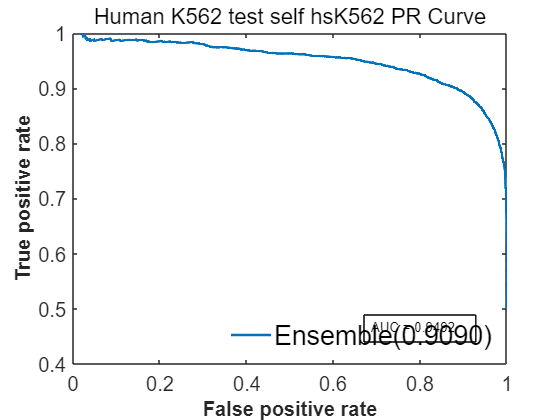

    plot(Xpr, Ypr,'LineWidth', 1.9);
    xlabel('recall', 'FontSize', 15, 'FontWeight', 'bold');
    ylabel('precision', 'FontSize', 15, 'FontWeight', 'bold');
    %xlabel('False Positive Rate');
    %ylabel('True Positive Rate');
    %title('Human Lung test hsLung PR Curve');
    titleString = sprintf("Human %s test self hs%s PR Curve", anycell,anycell);
    title(titleString);

    % 计算 AUC 并添加到图中（右下角）
    AUC_text = sprintf('AUC = %.4f', AUCpr);
    dim = [.65 .1 .2 .15]; % 定义文本框位置 [x y w h]
    annotation('textbox',dim,'String',AUC_text,'FitBoxToText','on');
    
    % 保存图像为 PNG 文件，并将 AUC 值添加到图中
    pngString = sprintf("Human_%s_test_self_hs%s_PR_curve_with_AUC.png", anycell,anycell);
    saveas(gcf, pngString, 'png');
    %saveas(gcf, 'Human_Lung_test_hsLung_PR_curve_with_AUC.png', 'png');


%%plot(Xpr, Ypr, 'LineWidth', 1.5)
%%hold on

set(gca, 'FontSize', 15)
LEG = legend({'Ensemble(0.9090)'}, 'Location', 'southeast');
LEG.FontSize = 20;
legend boxoff
xlabel('False positive rate', 'FontSize', 15, 'FontWeight', 'bold');
ylabel('True positive rate', 'FontSize', 15, 'FontWeight', 'bold');


    openfile = sprintf("trainingWindowIntdisStForR_hs%s.bed", anycell);
    fileID = fopen(openfile)

fileID = 571

    %fileID=fopen("trainingWindowIntdisStForR1_hsLung.bed");    %%%%%%%%%%%%%
    TrainwindowdatadisKc167=textscan(fileID,'%s %f %f %f %f %f %f %f');
    trainingdischiapetKc167=[TrainwindowdatadisKc167{2:8}];
    
    predictorNames = {'EGC', 'GS', 'DIS', 'EWS', 'GWS', 'EEC'};
    inputTable = array2table(trainingdischiapetKc167, 'VariableNames', {'EGC', 'GS', 'DIS', 'EWS', 'GWS', 'EEC', 'column_7'});
    predictors = inputTable(:, predictorNames);
    response = inputTable.column_7;
    isCategoricalPredictor = [false, false, false, false, false, false];
    %Ensemble bagged
    %%%%%% template = templateTree(...
    %%%%%%     'MaxNumSplits', 30);
    %%%%%% classificationEnsemble = fitcensemble(...
    %%%%%%     predictors, ...
    %%%%%%     response, ...
    %%%%%%     'Method', 'AdaBoostM1', ...
    %%%%%%     'NumLearningCycles', 30, ...
    %%%%%%     'Learners', template, ...
    %%%%%%     'LearnRate', 0.8, ...
    %%%%%%     'ClassNames', [1; 2]);

%#####################

template = templateTree('MaxNumSplits', 24);
classificationEnsemble = fitcensemble(predictors, response, 'Method', 'GentleBoost', 'NumLearningCycles', 5, 'Learners', template, 'LearnRate', 0.8, 'ClassNames', [1; 2]);
%%%%%% partitionedModel = crossval(classificationEnsemble, 'KFold', 10);
%%%%%% [validationPredictions, validationScores] = kfoldPredict(partitionedModel);


%######################


str =["hs_adrenal_gland_tissue_female_adult_51_year","hs_female_adult_53_years_tibial_nerve_tissue","hs1BD5","hs3AA3","hs12Z","hs16HBE14o-","hs92-1","hs402-91","hs501mel","hs786-0","hs786-M1A","hs3565_cells","hsA382","hsAdipose_derived_stem_cells","hsALL_xenograft_cells","hsAska","hsAsPC1","hsBeas-2B_airway_epithelial_cells","hsBIN-67","hsBJ_Fibroblast","hsBM-hMSC-TERT4_osteAdlast_diff_1d","hsBM-hMSC-TERT4_osteAdlast_diff_3d","hsBM-hMSC-TERT4_osteAdlast_diff_4h","hsBM-hMSC-TERT4_osteAdlast_diff_7d","hsBM-hMSC-TERT4_osteAdlast_diff_14d","hsBM-hMSC-TERT4_osteoblast_diff_1d","hsBM-hMSC-TERT4_osteoblast_diff_3d","hsBM-hMSC-TERT4_osteoblast_diff_4h","hsBM-hMSC-TERT4_osteoblast_diff_7d","hsBM-hMSC-TERT4_undifferentiated","hsBT-474","hsBT-549","hscaki-1","hsCal27","hsCAMA1","hsccRCC","hscortical_interneuron","hsCRL7250","hsCT27","hsD283","hsD341","hsDetroit_562","hsDKO","hsDND-41","hsEahy926","hsendometrial_epithelial_cells","hsEwing_sarcoma_cell_line_SKMNC","hsF1-ECs","hsF1-FBs","hsF2-ECs","hsF2-FBs","hsfetal_lung_fibroblast","hsFP-RMS","hsFT282","hsFU-UR-1","hsG401","hsGI-ME-N","hsGIST-T1","hsGlioblastoma_neurosphere_cell_suspensions","hsGM06990","hsGM12878","hsGM12890","hsGRANTA-519","hsGSC23","hsH1-hESC","hsH23","hsH69_cholangiocyte_cell_line","hsH209","hsH295R","hsH460","hsHAEC","hsHAP-1","hsHCC","hsHCC70","hsHCC827","hsHCC1143","hsHCC1806","hsHCC1937","hsHCC4006","hsHCT116","hsHEL","hsHT1080","hsHUAEC","hsHUES8","hsHUH7.5","hsHuh7","hsHuman_bladder_tumor_organoid","hshuman_colorectal_cancer_cells","hsHuman_epithelial_KB_cells","hshuman_Fetal_Osteoblasts_hFOB","hshuman_foreskin_fibroblasts_HFF","hsHuman_primary_adult_proerythroblasts_ProEs_from_CD34#_HSPC","hsImmortalized_human_mammary_epithelial_cells","hsIshikawa","hsJJN3","hsJ-Lat_A72","hsK562","hsKARPAS-422","hsKasumi-3","hsKG-1","hsKMS11","hsKMS27","hsKYSE-30","hsKYSE70","hsKYSE140","hsKYSE150","hsL-C-B","hsLiposarcoma_cells","hsLNCaP-FGC","hsLOUCY","hslow_passage_primary_melanoma_cultures","hsLUHMES","hsM14","hsMammary_gland_ductal_carcarcinoma_epithelial_cells_derived_from_metastatic_site","hsMB468","hsMCF-7","hsMCF10A_ER-Src_cells","hsMCF10CA1a","hsMDA-MB-134","hsMDA-MB-157","hsMDA-MB-231-Erbeta","hsMDA-MB-436","hsMDA-MB-468","hsmedial_ganglionic_eminence_neuronal_precursor","hsMedulloblastoma","hsMG63-3","hsML-1_DMSO_6h","hsML-1_IBRD9_6h","hsMLL-AF4_childhood_ALL_patient_3_blasts","hsMLL-AF4_infant_ALL_patient_2_blasts","hsMOLM-14_MLL-AF9","hsMOLT-4","hsMR42D","hsMV411_DMSO_6h","hsMV411_IBRD9_6h","hsNALM-6","hsNB69","hsNCI.H660","hsNCI-H82","hsNCIH211","hsNCIH441","hsNCI-H446","hsNCIH460","hsNCIH2107","hsNeuronal_Progenitor_cell_NPC","hsNK92","hsNTKO","hsOCI-AML2","hsOCIAML3","hsOCI-AML3_NPM1c_degron2_cell_line","hsOCIAML-3-NPM1c-FKBP12","hsOVCAR3","hsOvcar8","hsPaediatric_pro_B-cell_line_derived_from_ALL_with_t_4.11_q21.q23_translocation","hsPancreatic_Ductal_Adenocarcinoma_PDAC_cell_line","hsPC-9","hsPEO1","hsPodocyte","hsprimary_AML_cells","hsPsoas_Muscle","hsPulmonary_Artery_Endothelial_cells","hsRD","hsRH4","hsRKO","hsRMC-2C","hsRMG-1","hsRPMI8226","hsRPMI-8402","hsSAH","hsSCC1","hsSCC25","hsSCLC_ASCL1_positive","hsSET2","hsSHEP-21N","hsSiHa","hsSIRT6.2-7","hsSKBR3","hsSKMEL28","hsSKmel147","hsSK-N-AS","hsSK-N-BE2","hsSK-N-DZ","hsSK-N-FI","hsSK-N-MC","hsSKOV3","hsSNB19","hsSU-CCS-1_RRID.CVCL_B470","hsSU-DHL2","hsSUDHL-4","hsSU-DHL6","hsSUIT2","hsSUM44PE_breast_carcinoma_cell_line","hsSUM149","hsSUM149PT","hsSUM159","hsSUM229","hsSUM-229PE","hsSUP-B15","hsSuspension_HeLa_cells","hsSW620","hsSW1990","hsTL-Om1","hsU87MG","hsU937","hsU937_DMSO_6h","hsU937_IBRD9_6h","hsU937-PR9","hsU3008","hsU3009","hsU3013","hsU3028","hsU3031","hsU3042","hsU3054","hsU3073","hsU3078","hsU3085","hsU3086","hsU3118","hsU3121","hsUACC812","hsVH10","hsWERI-Rb-1","hsWI-38","hsWIBR2","hsWS8","hsWT_hiPSC#1","hsZNF532-NUT_24335"]

str = 1×228 string 数组
    "hs_adrenal_gland_tissue_female_adul…"    "hs_female_adult_53_years_tibial_ner…"    "hs1BD5"    "hs3AA3"    "hs12Z"    "hs16HBE14o-"    "hs92-1"    "hs402-91"    "hs501mel"    "hs786-0"    "hs786-M1A"    "hs3565_cells"    "hsA382"    "hsAdipose_derived_stem_cells"    "hsALL_xenograft_cells"    "hsAska"    "hsAsPC1"    "hsBeas-2B_airway_epithelial_cells"    "hsBIN-67"    "hsBJ_Fibroblast"    "hsBM-hMSC-TERT4_osteAdlast_diff_1d"    "hsBM-hMSC-TERT4_osteAdlast_diff_3d"    "hsBM-hMSC-TERT4_osteAdlast_diff_4h"    "hsBM-hMSC-TERT4_osteAdlast_diff_7d"    "hsBM-hMSC-TERT4_osteAdlast_diff_14d"    "hsBM-hMSC-TERT4_osteoblast_diff_1d"    "hsBM-hMSC-TERT4_osteoblast_diff_3d"    "hsBM-hMSC-TERT4_osteoblast_diff_4h"    "hsBM-hMSC-TERT4_osteoblast_diff_7d"    "hsBM-hMSC-TERT4_undifferentiated"    "hsBT-474"    "hsBT-549"    "hscaki-1"    "hsCal27"    "hsCAMA1"    "hsccRCC"    "hscortical_interneuron"    "hsCRL7250"    "hsCT27"    "hsD283"    "hsD341"    "hsDetroit_562"    "h


colnum = size(str, 2);

%创建文件目录
folderName = sprintf("predictanycell_%s", anycell);
mkdir(folderName);


% 检查是否成功创建目录
    if exist(folderName, 'dir') == 7
        disp(['目录 ' folderName ' 创建成功。']);
    else
        disp(['无法创建目录 ' folderName '。']);
    end

    "目录 "    "predictanycell_K562"    " 创建成功。"




for i = 1:colnum
    filename = strcat("cellAllfeatures", string(str(i)), ".bed");
    fileID = fopen(filename);
    Predictwindowdata = textscan(fileID, '%s %f %f %f %f %f %f');
    Allwindowdata = [Predictwindowdata{2:7}];
    [ensemblelabels, ensemblescores] = predict(classificationEnsemble, Allwindowdata);
    PredictRes = [Predictwindowdata, ensemblescores];
    %filenewname = strcat("Predictanycell/Prediction_placenta_", string(str(i)), ".txt");
    %filenewname = strcat(folderName,"/Prediction_", anycell,string(str(i)), ".txt");
    predictdir = sprintf("%s/Prediction_%s_%s.txt", folderName,anycell,string(str(i)));
    filenewname = strcat(predictdir);
    fid = fopen(filenewname, 'wt');
    
    AA = cellstr(PredictRes{1});
    BB=[PredictRes{8}];
    %BB = PredictRes{2};  %GPT result is empty
    Len = size(AA, 1);
    
    for j = 1:Len
        if BB(j) >= 0
            fprintf(fid, '%s\t%f\n', AA{j}, BB(j));
        end
    end
    
    % Close the file if the file identifier is valid
    if fid > 0
        fclose(fid);
    end
end
    




